1.產生 5000 個正規分佈亂數 ，畫出分為25類的直方圖

- 觀察並回答當亂數個數改變時，圖形有何變化?    **(10分)**

- 觀察並回答當分類個數改變時，圖形有何變化?    **(10分)**

x=randn(5000,1)

x =     0.5371
   -0.4379
    0.3775
    0.4257
   -0.2261
    0.1465
    1.0498
    1.9296
   -0.3142
   -0.1509


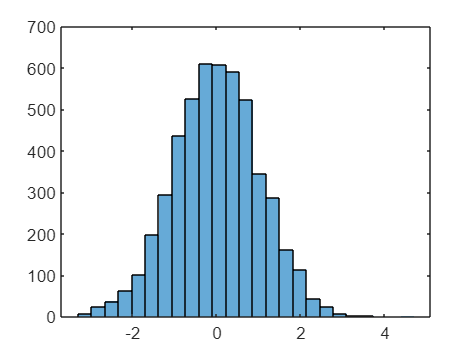

 histogram(x,25)

 x=randn(50000,1)

x =     1.1826
   -1.8127
    0.7440
   -0.8784
    0.6655
    0.8463
    1.0996
    1.1163
   -0.0645
   -0.0131


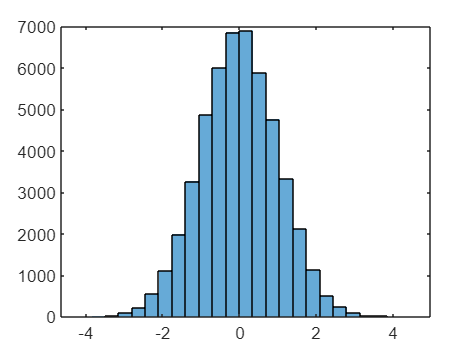

 histogram(x,25)

 %%個數越來越接近常數分布

 x=randn(5000,1)

x =    -0.0561
   -1.7670
   -0.8868
    0.9989
   -0.0151
   -0.8935
    2.0969
   -0.7719
    0.1002
    0.2098


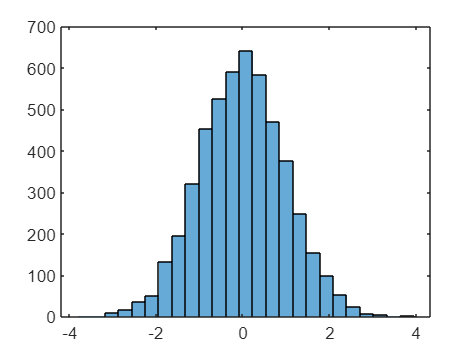

 histogram(x,25)

 x=randn(5000,1)

x =     1.0394
    1.3209
   -1.0051
    0.2904
   -2.3935
   -0.5653
   -0.3100
    0.5848
    0.6613
   -0.2048


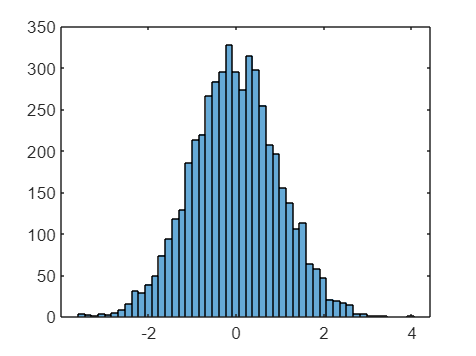

 histogram(x,50)

 %%左右越來越細致

2.分別畫出正絃波的下列圖形，並在每個圖形中都加入 title, xlabel, ylabel, legend

- 連續圖形 (黑色虛線)   **(7分)**

- 階梯圖 (紅色直線)      **(7分)**

- 針狀圖 (綠色圓)          **(7分)**

x=[0:0.1:pi*2]

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


y=sin(x)

y =          0    0.0998    0.1987    0.2955    0.3894    0.4794    0.5646    0.6442    0.7174    0.7833    0.8415    0.8912    0.9320    0.9636    0.9854    0.9975    0.9996    0.9917    0.9738    0.9463    0.9093    0.8632    0.8085    0.7457    0.6755    0.5985    0.5155    0.4274    0.3350    0.2392    0.1411    0.0416   -0.0584   -0.1577   -0.2555   -0.3508   -0.4425   -0.5298   -0.6119   -0.6878   -0.7568   -0.8183   -0.8716   -0.9162   -0.9516   -0.9775   -0.9937   -0.9999   -0.9962   -0.9825


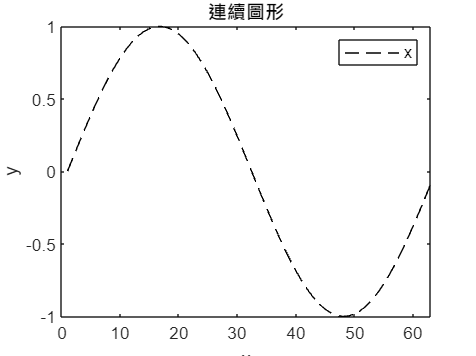

subplot(1,1,1),plot(y,'k--')
title("連續圖形")
xlabel("x") 
ylabel('y') 
legend('x')

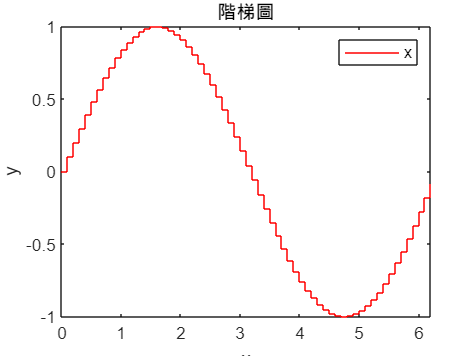


stairs(x,y,'r')
title("階梯圖")
xlabel("x") 
ylabel('y') 
legend('x')

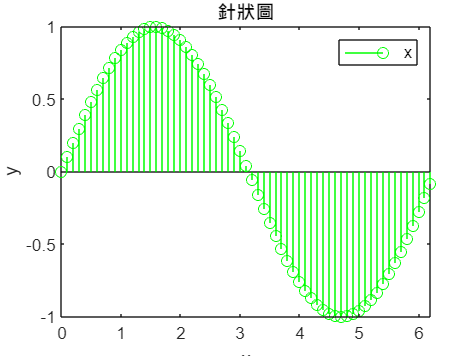


stem(x,y,'g')
title("針狀圖")
xlabel("x") 
ylabel('y') 
legend('x')

3.參考講義，取樣頻率為 1000 Hz，產生兩個正弦波組成的訊號(a=1, b=2)並將白雜訊加入   **(20分)**

- 利用subplot 顯示出四種白雜訊係數 0, 0.5, 1, 2，並畫出前50個點的圖形

t=(0:0.001:1)

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


a=1

a = 1

b=2

b = 2

y=a*sin(2*pi*50*t)+b*sin(2*pi*120*t)

y =          0    1.6781    2.5838    2.3500    1.2017   -0.1756   -1.0135   -0.8796    0.0904    1.2725    1.9021    1.5006    0.1485   -1.5453   -2.7607   -2.9021   -1.9146   -0.3116    1.1009    1.6556    1.1756    0.0584   -0.9532   -1.1870   -0.4180    1.0000    2.3202    2.8051    2.1288    0.5597   -1.1756   -2.2736   -2.2764   -1.3064    0.0125    0.9021    0.8586   -0.0728   -1.3240   -2.1187   -1.9021   -0.6545    1.0852    2.4977    2.9156    2.1756    0.7004   -0.7320   -1.4083   -1.0601


vaa=0

vaa = 0

yn0=y+0*randn(size(t))

yn0 =          0    1.6781    2.5838    2.3500    1.2017   -0.1756   -1.0135   -0.8796    0.0904    1.2725    1.9021    1.5006    0.1485   -1.5453   -2.7607   -2.9021   -1.9146   -0.3116    1.1009    1.6556    1.1756    0.0584   -0.9532   -1.1870   -0.4180    1.0000    2.3202    2.8051    2.1288    0.5597   -1.1756   -2.2736   -2.2764   -1.3064    0.0125    0.9021    0.8586   -0.0728   -1.3240   -2.1187   -1.9021   -0.6545    1.0852    2.4977    2.9156    2.1756    0.7004   -0.7320   -1.4083   -1.0601


yn1=y+0.5*randn(size(t))

yn1 =     0.1845    1.9837    3.1105    1.2387    0.9418   -0.4434   -1.3424   -0.3688    0.3862    1.7485    2.3174    1.4779    0.2207   -1.4249   -1.6606   -3.3078   -1.2780   -0.7080    1.1736    0.6651    1.3232   -0.2023   -0.8326   -1.1709   -0.6780    0.9037    1.8816    2.5653    2.1967   -0.4998   -1.6681   -2.6896   -3.1024   -1.1944    0.2033    0.4927    0.8165   -0.5477   -0.9245   -1.7721   -2.9117   -0.6971    0.7350    2.2850    2.8684    2.9833    1.1671   -1.6874   -1.2922   -1.2164


yn2=y+1*randn(size(t))

yn2 =     0.1254    1.9048    2.2843    1.0847    0.6527    0.2109   -1.5315   -0.7804    1.1021   -1.4712    0.9993    3.0787   -0.3064   -1.9022   -4.0035   -3.0659   -2.1943   -1.4407    3.1940    1.5089    1.7273    2.2349    0.4256   -1.6446   -0.1113    0.9802    2.8181    2.2099    2.4688    0.4818   -2.5005   -2.3373   -0.7871   -0.9788    0.5800    1.1427    0.9258    0.0156   -0.6178   -1.6867   -2.1016   -0.6958   -0.1104    3.2904    2.1160    3.0007    0.4798   -0.7946   -1.0840   -0.6594


yn3=y+2*randn(size(t))

yn3 =    -0.9378    3.0048    0.7876   -0.0505    2.0041   -1.8766    1.0596    0.4626   -0.4563    4.9392    2.8285   -1.8056    1.4691    1.2406    0.7271   -3.4847   -0.7372    0.2444   -0.7601    1.0962    1.6146   -0.1867   -0.8789    0.3913   -0.7102    1.1986   -3.3888   -1.1798    4.4142    2.5636   -1.1405   -3.6186   -4.6026   -8.8620    0.0443    1.3879   -0.4583    1.2840   -0.8779   -2.3513   -2.6126   -0.4756    1.5027    2.0084    3.1072    4.1201    1.2844   -4.2963   -2.1828   -1.7666


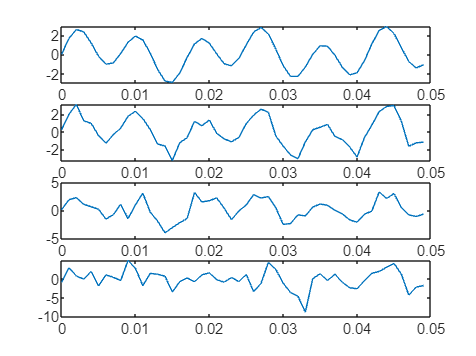

subplot(4,1,1),plot(t(1:50),yn0(1:50))
subplot(4,1,2),plot(t(1:50),yn1(1:50))
subplot(4,1,3),plot(t(1:50),yn2(1:50))
subplot(4,1,4),plot(t(1:50),yn3(1:50))

4.參考講義，在同一張圖畫出鋸齒波與方波，其中2秒內產生頻率為 40Hz，取樣速率為10kHz   **(20分)**

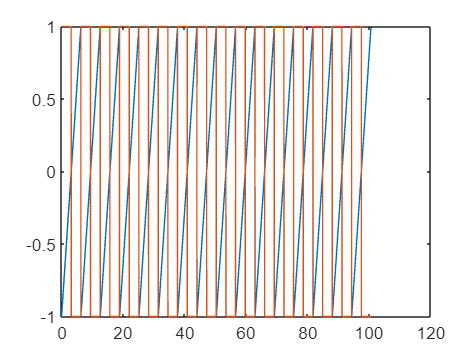

subplot(1,1,1)

fs=10000

fs = 10000

d=0:1/fs:2

d =          0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049


a=2*pi*40*d

a =          0    0.0251    0.0503    0.0754    0.1005    0.1257    0.1508    0.1759    0.2011    0.2262    0.2513    0.2765    0.3016    0.3267    0.3519    0.3770    0.4021    0.4273    0.4524    0.4775    0.5027    0.5278    0.5529    0.5781    0.6032    0.6283    0.6535    0.6786    0.7037    0.7288    0.7540    0.7791    0.8042    0.8294    0.8545    0.8796    0.9048    0.9299    0.9550    0.9802    1.0053    1.0304    1.0556    1.0807    1.1058    1.1310    1.1561    1.1812    1.2064    1.2315


y1=sawtooth(a)

y1 =    -1.0000   -0.9920   -0.9840   -0.9760   -0.9680   -0.9600   -0.9520   -0.9440   -0.9360   -0.9280   -0.9200   -0.9120   -0.9040   -0.8960   -0.8880   -0.8800   -0.8720   -0.8640   -0.8560   -0.8480   -0.8400   -0.8320   -0.8240   -0.8160   -0.8080   -0.8000   -0.7920   -0.7840   -0.7760   -0.7680   -0.7600   -0.7520   -0.7440   -0.7360   -0.7280   -0.7200   -0.7120   -0.7040   -0.6960   -0.6880   -0.6800   -0.6720   -0.6640   -0.6560   -0.6480   -0.6400   -0.6320   -0.6240   -0.6160   -0.6080


y2=square(a)

y2 =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


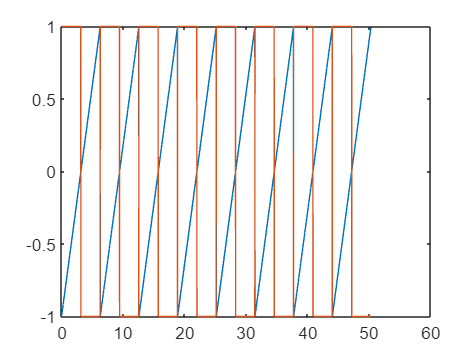

plot(a(1:2000),y1(1:2000),a(1:2000),y2(1:2000))

5.Generate “p_data1.txt” file, where the numerical values from data1.txt times 2. Next, follow the same procedure to generate “p_data2.txt”,  where the header are preserved.   **(20分)**

load C:\Users\LIN20\OneDrive\桌面\matlab\data1.txt
x=data1()

x =     0.0158   -0.0001
    0.0315   -0.0000
    0.0473    0.0001
    0.0631   -0.0000
    0.0788    0.0000
    0.0946    0.0000
    0.1104    0.0000
    0.1261    0.0002
    0.1419    0.0010
    0.1577    0.0009


x=x*2

x =     0.0315   -0.0002
    0.0631   -0.0000
    0.0946    0.0003
    0.1261   -0.0000
    0.1577    0.0001
    0.1892    0.0000
    0.2208    0.0001
    0.2523    0.0004
    0.2838    0.0021
    0.3154    0.0019


save C:\Users\LIN20\OneDrive\桌面\matlab\p_data1.txt -ascii x
	
A = 'C:\Users\LIN20\OneDrive\桌面\matlab\data2.txt'

A = 'C:\Users\LIN20\OneDrive\桌面\matlab\data2.txt'

B = 'C:\Users\LIN20\OneDrive\桌面\matlab\p_data2.txt'

B = 'C:\Users\LIN20\OneDrive\桌面\matlab\p_data2.txt'


file2=fopen(B,'w')

file2 = 14


%save C:\Users\LIN20\OneDrive\桌面\matlab\p_data2.txt -ascii fil

fill = importdata(A)

fill = struct with fields:
          data: [6×1 double]
      textdata: {2×1 cell}
    colheaders: {'---Head2'}


c=string(fill.textdata)

c = 2×1 string array
    "---Head1"
    "---Head2"


b=fill.data*2

b =    20.2000
    4.0000
   20.4000
   20.6000
   20.8000
   21.0000


fprintf(file2,'%s\n',c)

ans = 18

fprintf(file2,'%f\n',b)

ans = 59


fclose(file2)

ans = 0